# Data Analysis: Import and Process an Excel spreadsheet

#### by Rodolfo Muñoz

clear variables; close all; clc;

First we start by letting the user select the file.

[filename,path] = uigetfile('*.xls');
colors = [0.4 0.5 1; 0 0 0];

Then, we load the data into a datastore in case its a big file and select to read only one sheet at a time. Then we preview the table to select the data we need for the analysis. 

tabds = datastore([path filename],'Type',"spreadsheet");

tabds.ReadSize = 'sheet';
preview(tabds)

ans = 8×21 table
    RowID         OrderID           OrderDate      ShipDate           ShipMode          CustomerID        CustomerName           Segment            Country                City                State         PostalCode     Region           ProductID              Category           Sub_Category                                  ProductName                                 Sales     Quantity    Discount    Profit 
    _____    __________________    ___________    ___________    __________________    ____________    __

For this analysis we'll look over the sales values so we'll retrieve only a handful of columns from the table.

tabds.SelectedVariableNames = {'OrderDate','Sales','Quantity','Profit'};
tab = read(tabds);
sales = groupsummary(tab,{'OrderDate'},'sum');
stats.mean_Sales = mean(sales.sum_Sales); 
stats.mean_Quantity = mean(sales.sum_Quantity); 

## Plot sales data vs time

Now we plot the results to look at the data and guide the analysis:

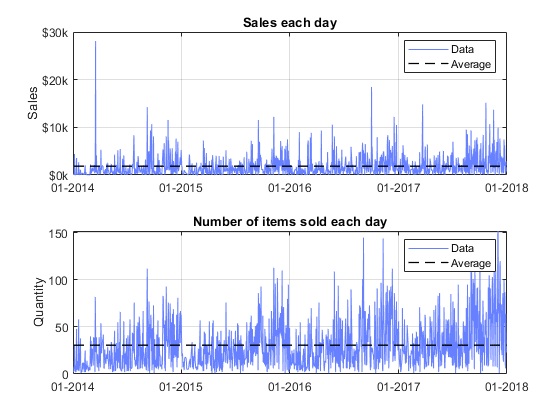

figure('name','sales');
subplot(2,1,1)
plotSales(sales.OrderDate,sales.sum_Sales,'$','lines',{'mean'});

subplot(2,1,2)
plotSales(sales.OrderDate,sales.sum_Quantity,'qty','lines',{'mean'});

## Analyze its frequency components

As seen in the items plot, there seems to be a yearly patron. For further analysis we see the Fourier Transform of the data to check the low frequency range.  

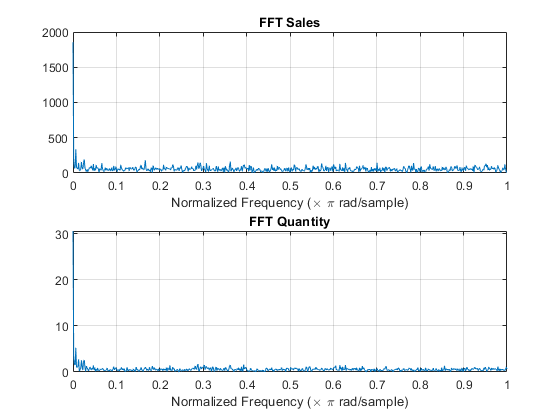

F_s = fft(sales.sum_Sales); F_s = F_s/length(F_s);
F_q = fft(sales.sum_Quantity); F_q = F_q/length(F_q);
w = (0:length(F_s)-1)/(length(F_s)-1)*2;

figure('name','FFT Sales');
subplot(2,1,1)
plot(w,abs(F_s))
xlim([0 1])
xlabel('Normalized Frequency (\times \pi rad/sample)')
title('FFT Sales')
grid on
subplot(2,1,2)
plot(w,abs(F_q))
xlim([0 1])
xlabel('Normalized Frequency (\times \pi rad/sample)')
title('FFT Quantity')
grid on

## Filter sales data

Both plots, specially the quantity one, seem to have a more defined pattern below $\omega =0\ldotp 05$. Therefore, we use a Chevyshev-II Low Pass Filter to look at the data:

Wp = 0.1;  % Passband frequency
Ws = Wp + 0.05;                    % Stopband frequency
Rp = 3;                            % Passband ripple (dB)
Rs = 60;                           % Stopband atenuation (dB)

[n,Ws] = cheb2ord(Wp,Ws,Rp,Rs);
[b,a] = cheby2(n,Rs,Ws);

And check the results on the **sales.sum_Quantity** data by applying the filter:

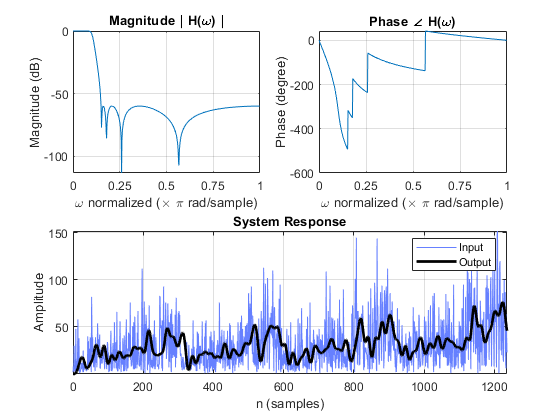

figure('name','Filter effect on data');
filterresponse(b,a,sales.sum_Quantity,'colors',colors,'magplot','indb','linewidth',2);

While the filtered data shows the pattern we intuited before, it has a phase delay because of the filter so the sales peaks are do not patch the dates of the original. For that we use the *filtfilt* function and get the results we want:

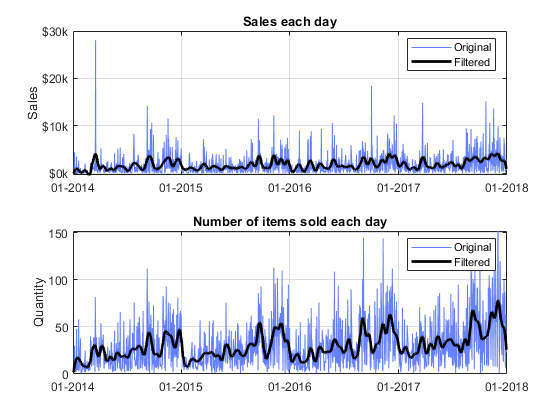

sales_smooth.qty = filtfilt(b,a,sales.sum_Quantity);
sales_smooth.sales = filtfilt(b,a,sales.sum_Sales);

figure("Name","Filtered data")
subplot(2,1,1)
plotSales(sales.OrderDate,sales.sum_Sales,'$')
hold on;
plot(sales.OrderDate,sales_smooth.sales/1e3,'color',colors(2,:),"LineWidth",2)
hold off;
legend('Original','Filtered')

subplot(2,1,2)
plotSales(sales.OrderDate,sales.sum_Quantity,'qty')
hold on;
plot(sales.OrderDate,sales_smooth.qty,'color',colors(2,:),"LineWidth",2)
hold off;
legend('Original','Filtered')
% fig2pdf('FilteredSales')

## Plot a comparison of the sales of each year 

After confirming the pattern, with peaks we separate the sales data by year to have focus on a yearly and see the data side-by-side in a same plot. *We also preallocate some variables for speed.*

sales_year = struct('years',unique(sales.OrderDate.Year),...
                    'lengths',[], ...
                    'dates',[],...
                    'sales',[],...
                    'sales_smooth',[]);

N = length(sales_year.years);
u = sales.OrderDate;
idx = (u.Year == ones(height(sales),1)*sales_year.years');
bisiesto = u(find((u.Day == 29).*(u.Month == 2), 1)).Year;
sales_year.lengths = sum(idx);

figure('Name','Daily sales comparisson');
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);
for i=1:N
    sales_year.dates{i} = u(idx(:,i));
    sales_year.dates{i}.Year = bisiesto;
    sales_year.sales{i} = sales.sum_Sales(idx(:,i));
    sales_year.sales_smooth{i} = sales_smooth.sales(idx(:,i));
    
    sales_year.qty{i} = sales.sum_Quantity(idx(:,i));
    sales_year.qty_smooth{i} = sales_smooth.qty(idx(:,i));
    
    sales_year.profit{i} = sales.sum_Profit(idx(:,i));
    
    axes(ax1); hold on;
    plotSales(sales_year.dates{i},sales_year.sales_smooth{i}, ...
         'color',[1-i/N 0.5*i/N i/N])    
    axes(ax2); hold on;
    plotSales(sales_year.dates{i},sales_year.qty_smooth{i},'qty', ...
         'color',[1-i/N 0.5*i/N i/N])
end

And now add the finishing touch with more detail on the time axis.

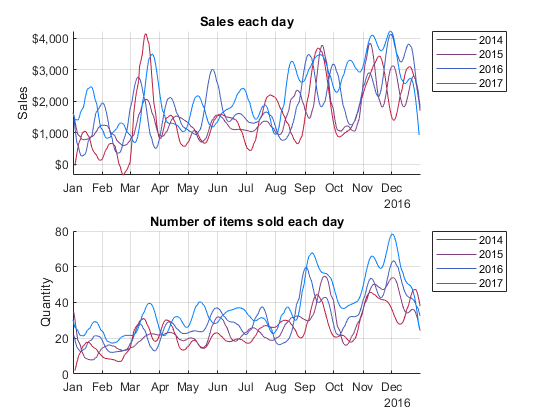

axes(ax1)
xticks(datetime(bisiesto,1:12,1))
xtickformat('MMM')
legend(num2str(sales_year.years),'Location',"northeastoutside")
axes(ax2)
xticks(datetime(bisiesto,1:12,1))
xtickformat('MMM')
legend(num2str(sales_year.years),'Location',"northeastoutside")
% fig2pdf('YearlySales')

## Check distribution with boxplots

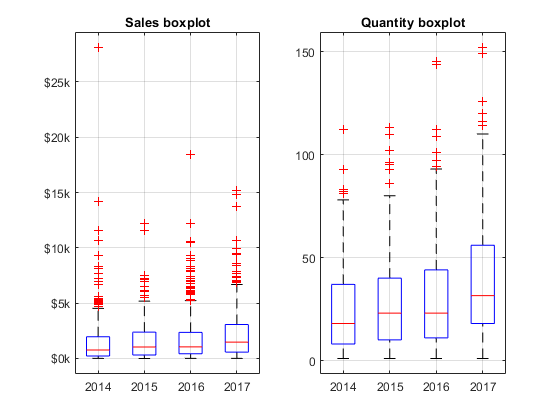

figure('Name','Boxplots');
g = [];
for i = 1:length(sales_year.years)
    g = [g; repmat({num2str(sales_year.years(i))},sales_year.lengths(i),1)];
end

subplot(1,2,1)
boxplot(sales.sum_Sales/1e3,g)
ytickformat('$%.0fk')
title('Sales boxplot')
grid on;

subplot(1,2,2)
boxplot(sales.sum_Quantity,g)
title('Quantity boxplot')
grid on;